We look at the balance between the axial spring and the radial spring to lock the claw in position

clear
clf

considering a constant spring constant we get the pull of one **axial spring** from SODEMANN

k_axial = 0.29e3; % N/mm --> N/m % max kraft 47,43, max vandring 140,97, total lenth 229,87
% varenummer 	E07500633500S trækfjeder SODEMANN
x_axial = 140e-3; % udspændt fjeder til træk af claw
F_spring_axial = k_axial * x_axial

F_spring_axial = 40.6000

Magnet axial lock

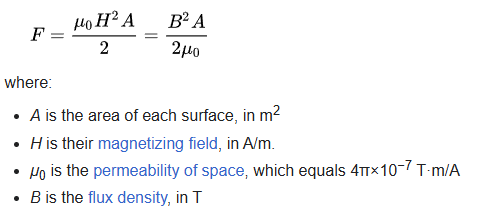

https://en.wikipedia.org/wiki/Force_between_magnets

g = 9.82;
x_contact = 1.85e-4

x_contact = 1.8500e-04

d_magnet = 27e-3; %chrome-extension://efaidnbmnnnibpcajpcglclefindmkaj/https://www.supermagnete.dk/data_sheet_CS-S-27-04-N.pdf
r_magnet = d_magnet/2;
L = 4e-3; % https://www.supermagnete.dk/magneter-til-at-skrue-pa/skivemagnet-27mm-hjde-4mm_CS-S-27-04-N?group=lp-screwable-magnets
A = pi*(d_magnet/2)^2

A = 5.7256e-04

mu = 1.25663706e-6; %(1,25663706·10^(−6)  (T·m)/A).
% M1 = 0.5; % tesla
% M2 = M1;

kgF = 8; %kg

syms B
F_magnet_in = kgF * g% / (1 + x_contact^2)

F_magnet_in = 78.5600

F_eq = F_magnet_in == B^2 * A / (2*mu);

B_sol = solve(F_eq, B);
B = double(B_sol(2))

B = 0.5872


x=x_contact

x = 1.8500e-04


F_magnet = ((B^2 * A^2 * (L^2 * r_magnet^2)) / (pi * mu * L^2)) * ( 1 / x^2 + 1 / (x+2*L)^2 - 2/(x+L)^2)

F_magnet = 151.9655


% F = mu/(4*pi) * M1 * M2 / x_contact^2

% 

Frication acting on the calw is devided in to two kinds that are added up.

- Due to gravity we find

m_claw = 1; %kg <--------- differ between claws
f_s = 0.30;

F_claw_fric = g * m_claw * f_s

F_claw_fric = 2.9460

syms F_n_x
F_n_x_eq = 0 == F_spring_axial - F_magnet - F_claw_fric + F_n_x;

F_n_x_sol = solve(F_n_x_eq, F_n_x);

F_n_x_sol = double(F_n_x_sol)

F_n_x_sol = 114.3115

plot

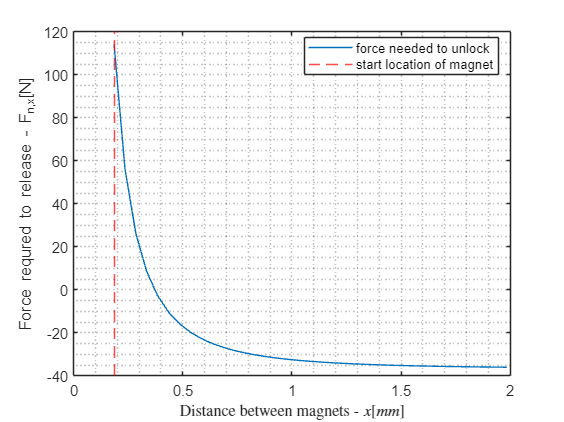

syms F_n_x
x_slut = 2e-3;
xs = x_contact:5e-5:x_slut; %Distance between magnets
for i = 1:length(xs)
    % F_magnet = 6 * g * 2 / (1 + xs(i)^2);
    
    F_magnet = ((B^2 * A^2 * (L^2 * r_magnet^2)) / (pi * mu * L^2)) *... 
    ( 1 / xs(i)^2 + 1 / (xs(i)+2*L)^2 - 2/(xs(i)+L)^2);

    x_axial = 140e-3 - xs(i); % udspændt fjeder til træk af claw
    F_spring_axial = k_axial * x_axial;

    % F_magnet = mu/(4*pi) * M1 * M2 / xs(i)^2;
    F_n_x_eq = 0 == F_spring_axial - F_magnet - F_claw_fric + F_n_x;

    F_n_x_sol = solve(F_n_x_eq, F_n_x);

    F_n_x_sols(i) = double(F_n_x_sol);
end

plot(xs*1000, F_n_x_sols, DisplayName="force needed to unlock")
hold on

xline(x_contact*1000,'r--', DisplayName="start location of magnet")
xlabel("Distance between magnets - $x [mm]$", Interpreter="latex")
ylabel("Force requred to release - F_{n,x}[N]")
grid("minor")
legend(location='best')
hold off